# **Inverse Kinematics RRP**

## Inverse Kinematics of the given manipulator and End effector pose

#### Defining the Robot links using DH and making the robot model

L(1)=Link([0 1 0 pi/2]); %offset d a alpha, default revolute, 1 for prismatic
L(2)=Link([0 0 1 pi/2 0 pi/2]);
L(3)=Link([0 0 0 0 1]);
robo=SerialLink(L,'name','robo')

 
robo = 
 
robo (3 axis, RRP, stdDH, fastRNE)                               
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          1|          0|      1.571|          0|
|  2|         q2|          0|          1|      1.571|      1.571|
|  3|          0|         q3|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0              
       9.81         0  0  1  0           0  0  1  0              
                    0  0  0  1           0  0  0  1              
 


#### Finding the joint parameters

theta1=atan2(-0.184,0.106)

theta1 = -1.0481

theta2=atan2(-0.612,0.707*sin(theta1))

theta2 = -2.3567

d=(0.212-1-cos(theta2))/sin(theta2)

d = 0.1140

**Getting the forward kinematics solution and plotting the robot**

robo.fkine([theta1,theta2,d])

ans =     0.3528   -0.8665   -0.3531    0.3126
   -0.6124   -0.4992    0.6130   -0.5425
   -0.7075    0.0000   -0.7068    0.2120
         0         0         0    1.0000


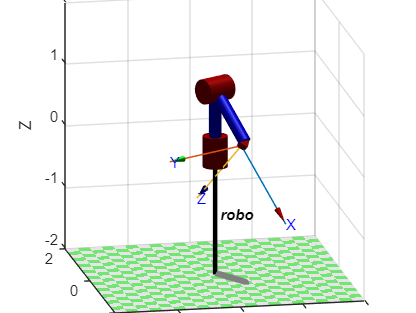

robo.plot([theta1,theta2,d],'workspace',[-2 2 -2 2 -2 2])